% Var 4
% f(x) = 10+x^2-10*cos(2*pi*x)
% f(x,y) = (1.5-x+x*y)^2+(2.25-x+x*y^2)^2+(2.625-x+x*y^3)^2

% Task 1

fminbnd(@fun1,-1,5000,optimset('Display','iter','TolX',1e-200))

 
 Func-count     x          f(x)         Procedure
    1        1909.21   3.6451e+06        initial
    2        3089.79   9.5468e+06        golden
    3        1179.58  1.39142e+06        golden
    4        728.636       530927        golden
    5         449.94       202447        golden
    6        277.696      77128.5        golden
    7        171.244        29334        golden
    8        105.452      11139.8        golden
    9        64.7912      4205.34        golden
   10        39.6612      1588.31        golden
   11          24.13      585.413        golden
   12        14.5312      230.964        golden
   13        2.54799      26.0411        parabolic
   14      -0.768411      9.43622        parabolic
   15       0.498342      20.2478        golden
   16      -0.284555      12.2351        golden
   17      -0.583595      18.9926        golden
   18       -0.85687      4.51273        golden
   19      -0.911541      2.33614        golden
   20      -0.945329      1.4

ans = -0.9950

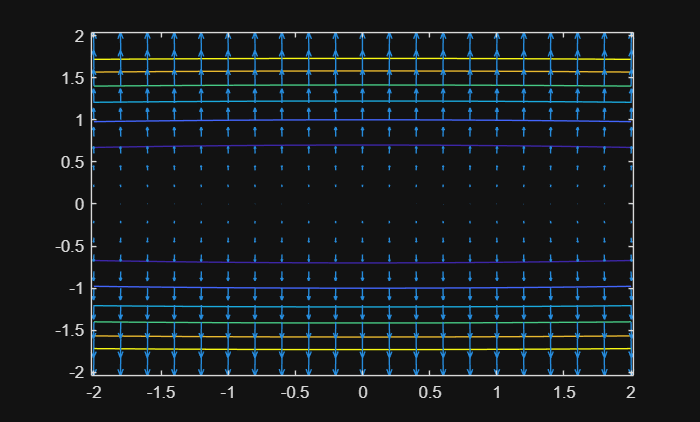

% Task 2

% use meshgrid to create a rectangular grid
[x,y]=meshgrid(-2:.2:2,-1.8:.2:1.8);
% compute function values at the points of the grid
z=x.^2+100*y.^2;
% compute gradients
% dx – partial derivative in respect of x; dy – partial derivative in respect of y
[dx,dy]=gradient(z);
% plot contourlines
contour(x,y,z)
% the next plot will be constructed on top of the existing figure
hold on
% plot gradients
quiver(x,y,dx,dy)
% finish drawing
hold off

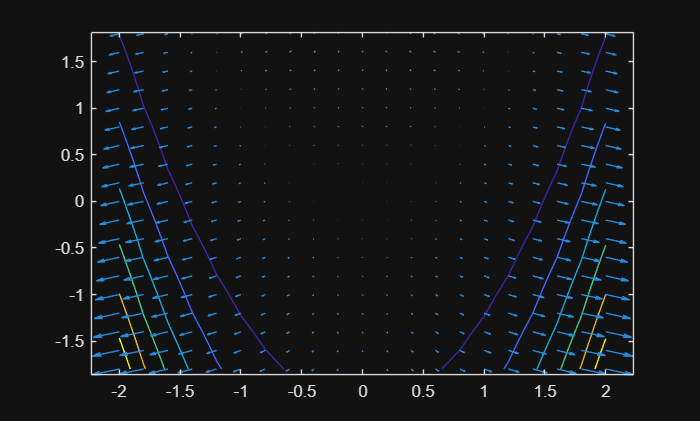



% use meshgrid to create a rectangular grid
[x,y]=meshgrid(-2:.2:2,-1.8:.2:1.8);
% compute function values at the points of the grid
z=100*(y-x.^2).^2+(1-x).^2;
% compute gradients
% dx – partial derivative in respect of x; dy – partial derivative in respect of y
[dx,dy]=gradient(z);
% plot contourlines
contour(x,y,z)
% the next plot will be constructed on top of the existing figure
hold on
% plot gradients
quiver(x,y,dx,dy)
% finish drawing
hold off

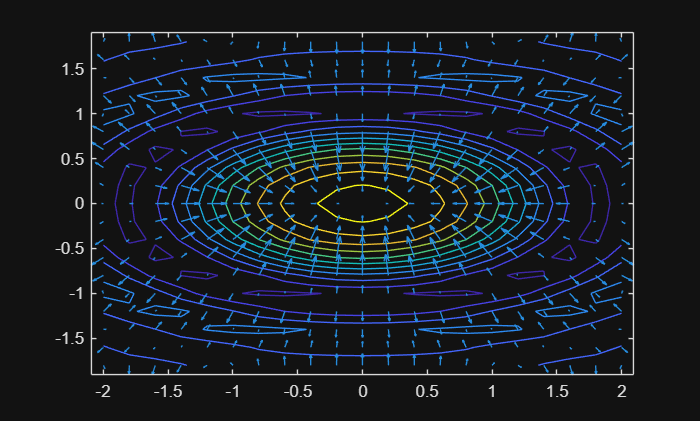




% use meshgrid to create a rectangular grid
[x,y]=meshgrid(-2:.2:2,-1.8:.2:1.8);
% compute function values at the points of the grid
z=(sin(x.^2+3*y.^2+1))./(x.^2+3*y.^2+1);
% compute gradients
% dx – partial derivative in respect of x; dy – partial derivative in respect of y
[dx,dy]=gradient(z);
% plot contourlines
contour(x,y,z)
% the next plot will be constructed on top of the existing figure
hold on
% plot gradients
quiver(x,y,dx,dy)
% finish drawing
hold off

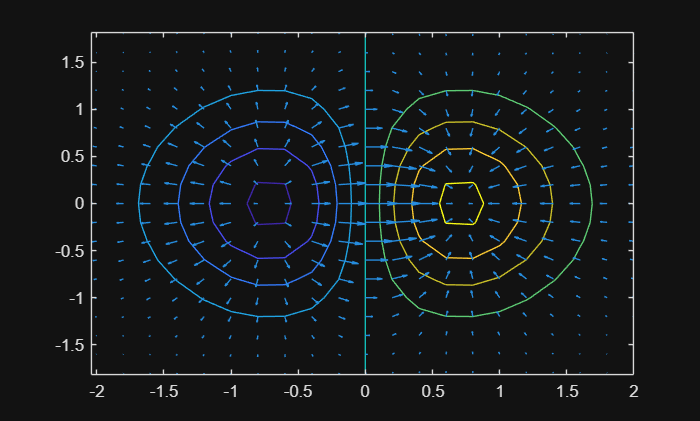





% use meshgrid to create a rectangular grid
[x,y]=meshgrid(-2:.2:2,-1.8:.2:1.8);
% compute function values at the points of the grid
z=x.*exp(-x.^2-y.^2);
% compute gradients
% dx – partial derivative in respect of x; dy – partial derivative in respect of y
[dx,dy]=gradient(z);
% plot contourlines
contour(x,y,z)
% the next plot will be constructed on top of the existing figure
hold on
% plot gradients
quiver(x,y,dx,dy)
% finish drawing
hold off

% Task 3

close all
clc

% computer gives a better result
disp(['Example 1: computer better than human eye' newline ...
      'Function: objfun' newline ...
      'Initial point: x0 = [0;0]'])

Example 1: computer better than human eye
Function: objfun
Initial point: x0 = [0;0]



x0 = [0;0];
options = optimoptions('fminunc', ...
    'Display','iter', ...
    'Algorithm','quasi-newton', ...
    'MaxFunctionEvaluations',5000, ...
    'MaxIterations',1000);

[x_comp1,fval_comp1,exitflag_comp1,output_comp1] = fminunc(@objfun,x0,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3              170                            22
     1          12          36.2175        0.11384           36.2  
     2          24          31.1344      0.0109847           29.7  
     3          30          5.60839        4.41199           24.2  
     4          33         0.598564              1           4.47  
     5          36         0.110654              1           4.12  
     6          39      0.000572997              1          0.191  
     7          42      1.79011e-05              1          0.033  
     8          45       5.5911e-10              1       0.000142  
     9          48      1.67345e-13              1       3.31e-06  

Local minimum found.

Optimization completed because the 

disp(['x_comp1 = ' mat2str(x_comp1) newline ...
      'fval_comp1 = ' num2str(fval_comp1) newline ...
      'exitflag_comp1 = ' num2str(exitflag_comp1) newline ...
      'iterations = ' num2str(output_comp1.iterations)])

x_comp1 = [2.9999999305957;2.00000000878468]
fval_comp1 = 1.6735e-13
exitflag_comp1 = 1
iterations = 9


disp(' ')



% human eye gives a better result
disp(['Example 2: human eye better than computer' newline ...
      'Function: objfun1' newline ...
      'Initial point: x0 = [0;0]'])

Example 2: human eye better than computer
Function: objfun1
Initial point: x0 = [0;0]



x0 = [0;0];
options = optimoptions('fminunc', ...
    'Display','iter', ...
    'Algorithm','quasi-newton', ...
    'MaxFunctionEvaluations',5000, ...
    'MaxIterations',1000);

[x_human1,fval_human1,exitflag_human1,output_human1] = fminunc(@objfun1,x0,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3                8                             8
     1           6             2.25          0.125              3  
     2           9          1.01497              1           1.95  
     3          12        0.0305875              1          0.634  
     4          15      0.000949099              1          0.123  
     5          18      1.75802e-06              1        0.00274  
     6          21      2.88713e-09              1       0.000107  
     7          24      2.86398e-13              1       1.79e-06  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

disp(['x_human1 = ' mat2str(x_human1) newline ...
      'fval_human1 = ' num2str(fval_human1) newline ...
      'exitflag_human1 = ' num2str(exitflag_human1) newline ...
      'iterations = ' num2str(output_human1.iterations)])

x_human1 = [2.00000026943786;-0.999999768806976]
fval_human1 = 2.864e-13
exitflag_human1 = 1
iterations = 7






% Changed initial point - computer example
disp(['Computer example with changed initial point' newline ...
      'Function: objfun' newline ...
      'Initial point: x0 = [1;-2]'])

Computer example with changed initial point
Function: objfun
Initial point: x0 = [1;-2]



x0 = [1;-2];
options = optimoptions('fminunc', ...
    'Display','iter', ...
    'Algorithm','quasi-newton', ...
    'MaxFunctionEvaluations',5000, ...
    'MaxIterations',1000);

[x_comp2,fval_comp2,exitflag_comp2,output_comp2] = fminunc(@objfun,x0,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3              148                            52
     1          12         0.757205      0.0489136           5.48  
     2          18         0.249677            0.5           4.86  
     3          24       0.00128432       0.298844           0.41  
     4          27      2.73485e-05              1           0.04  
     5          30      2.25578e-09              1       0.000613  
     6          33      1.71623e-12              1       1.75e-05  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<<a href = "matlab

disp(['x_comp2 = ' mat2str(x_comp2) newline ...
      'fval_comp2 = ' num2str(fval_comp2) newline ...
      'exitflag_comp2 = ' num2str(exitflag_comp2) newline ...
      'iterations = ' num2str(output_comp2.iterations)])

x_comp2 = [3.58442846604299;-1.84812630881381]
fval_comp2 = 1.7162e-12
exitflag_comp2 = 1
iterations = 6



disp(' ')





% Changed initial point - human eye example
disp(['Human eye example with changed initial point' newline ...
      'Function: objfun1' newline ...
      'Initial point: x0 = [5;10]'])

Human eye example with changed initial point
Function: objfun1
Initial point: x0 = [5;10]



x0 = [5;10];
options = optimoptions('fminunc', ...
    'Display','iter', ...
    'Algorithm','quasi-newton', ...
    'MaxFunctionEvaluations',5000, ...
    'MaxIterations',1000);

[x_human2,fval_human2,exitflag_human2,output_human2] = fminunc(@objfun1,x0,options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3              493                            88
     1           9          9.37397       0.113636              8  
     2          12          2.83609              1           3.37  
     3          15          1.28458              1           2.17  
     4          18        0.0555943              1          0.856  
     5          21       0.00203974              1          0.179  
     6          24      6.09837e-06              1        0.00518  
     7          27      1.30756e-08              1       0.000228  
     8          30      2.30041e-12              1          5e-06  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

disp(['x_human2 = ' mat2str(x_human2) newline ...
      'fval_human2 = ' num2str(fval_human2) newline ...
      'exitflag_human2 = ' num2str(exitflag_human2) newline ...
      'iterations = ' num2str(output_human2.iterations)])

x_human2 = [1.99999916469828;-0.999999367015784]
fval_human2 = 2.3004e-12
exitflag_human2 = 1
iterations = 8


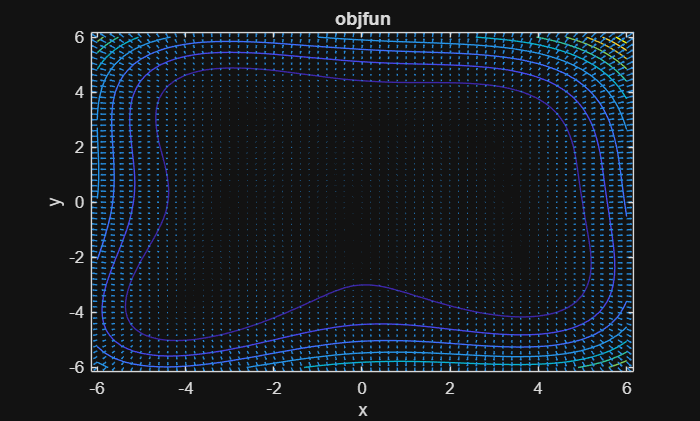




% visualization of objfun (computer gives a better result)
figure
[x,y] = meshgrid(-6:0.2:6,-6:0.2:6);

z = (x.^2 + y - 11).^2 + (x + y.^2 - 7).^2;

[dx,dy] = gradient(z,0.2,0.2);

contour(x,y,z)
hold on
quiver(x,y,dx,dy)
hold off
title('objfun')
xlabel('x')
ylabel('y')

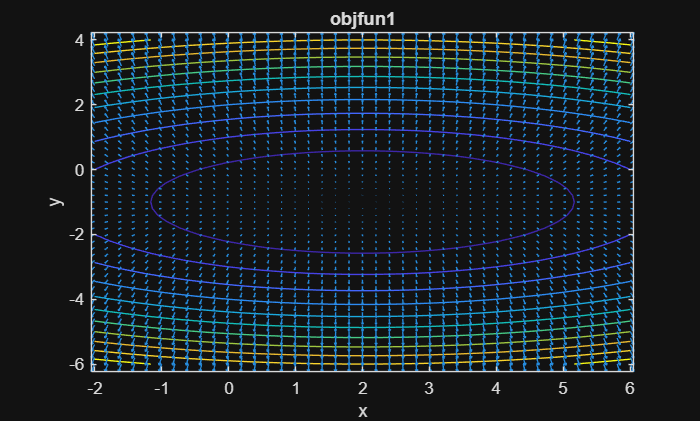



% visualization of objfun1 (human eye gives a better result)
figure
[x,y] = meshgrid(-2:0.2:6,-6:0.2:4);

z = (x - 2).^2 + 4*(y + 1).^2;

[dx,dy] = gradient(z,0.2,0.2);

contour(x,y,z)
hold on
quiver(x,y,dx,dy)
hold off
title('objfun1')
xlabel('x')
ylabel('y')

clear all
clc
syms x y

eq1 = 1.5 - x + x*y == 0;
eq2 = 2.25 - x + x*y^2 == 0;
eq3 = 2.625 - x + x*y^3 == 0;

sol = solve([eq1, eq2, eq3], [x, y]);

x_min = sol.x;
y_min = sol.y;

f_min = (1.5 - x_min + x_min*y_min)^2 + ...
        (2.25 - x_min + x_min*y_min^2)^2 + ...
        (2.625 - x_min + x_min*y_min^3)^2;

disp(['(x,y)_min = (' num2str(double(x_min)) ', ' num2str(double(y_min)) ')' newline ...
      'f_min = ' num2str(double(f_min))])

(x,y)_min = (3, 0.5)
f_min = 0


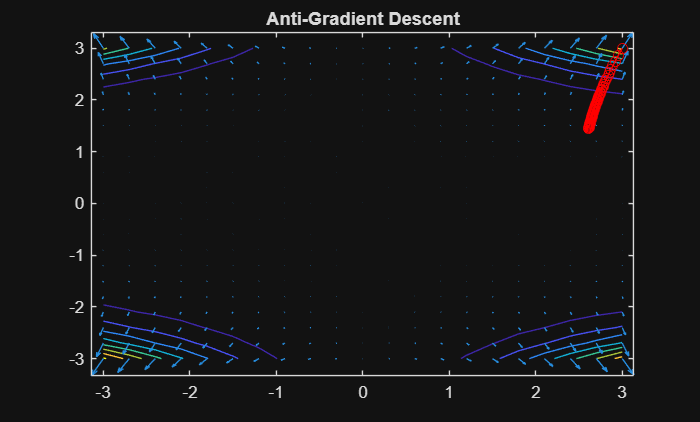

% Task 4
close all
clc

[x,y]=meshgrid(-3:.3:3);
z = (1.5 - x + x.*y).^2 + (2.25 - x + x.*y.^2).^2 + (2.625 - x + x.*y.^3).^2;
figure(1)
hold off
contour(x,y,z)
[dx,dy]=gradient(z,.2,.2);
hold on
quiver(x,y,dx,dy)
title('Anti-Gradient Descent')
x=[3,3];
xs=x;
itsk=100;
step=0.00001;
for i=1:itsk

 x = xs - step*gradient1(xs);
 plot([xs(1),x(1)],[xs(2),x(2)],'r',[xs(1),x(1)],[xs(2),x(2)],'ro')
 xs=x;
end

xs

xs =     2.6133    1.4449


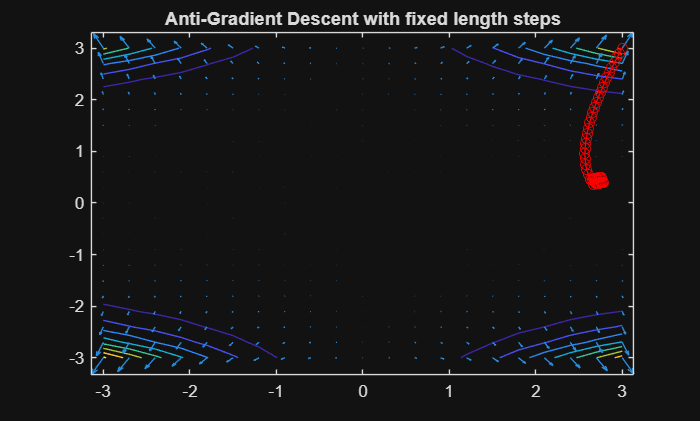

% Task 5
close all
clc

[x,y]=meshgrid(-3:.3:3);
z = (1.5 - x + x.*y).^2 + (2.25 - x + x.*y.^2).^2 + (2.625 - x + x.*y.^3).^2;
figure(1)
hold off
contour(x,y,z)
[dx,dy]=gradient(z,.2,.2);
hold on
quiver(x,y,dx,dy)
title('Anti-Gradient Descent with fixed length steps')
x=[3,3];
xs=x;
itsk=50;
step=0.1;
for i=1:itsk

 x = xs - step*(gradient1(xs)/norm(gradient1(xs)));
 plot([xs(1),x(1)],[xs(2),x(2)],'r',[xs(1),x(1)],[xs(2),x(2)],'ro')
 xs=x;
end

xs

xs =     2.7580    0.4942


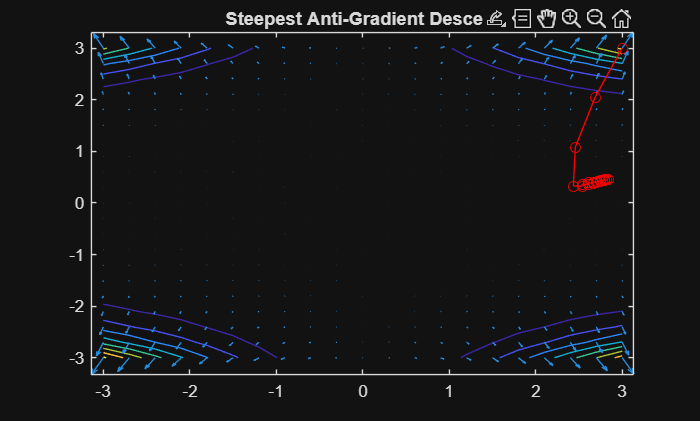

% Task 6
close all
clc

[x,y]=meshgrid(-3:.3:3);
z = (1.5 - x + x.*y).^2 + (2.25 - x + x.*y.^2).^2 + (2.625 - x + x.*y.^3).^2;
figure(1)
hold off
contour(x,y,z)
[dx,dy]=gradient(z,.2,.2);
hold on
quiver(x,y,dx,dy)
title('Steepest Anti-Gradient Descent')
x=[3,3];
xs=x;
itsk=20;
for i=1:itsk
s = -gradient1(xs)/norm(gradient1(xs));
% x = (xs(1)+step*s(1))
% y = (xs(2)+step*s(2))s
step = fminbnd(@(step) ...
    (1.5 - (xs(1)+step*s(1)) + (xs(1)+step*s(1))*(xs(2)+step*s(2)))^2 + ...
    (2.25 - (xs(1)+step*s(1)) + (xs(1)+step*s(1))*(xs(2)+step*s(2))^2)^2 + ...
    (2.625 - (xs(1)+step*s(1)) + (xs(1)+step*s(1))*(xs(2)+step*s(2))^3)^2, ...
    0,1);
 x = xs + step*s;
 plot([xs(1),x(1)],[xs(2),x(2)],'r',[xs(1),x(1)],[xs(2),x(2)],'ro')
 xs=x;
end

xs

xs =     2.8376    0.4513


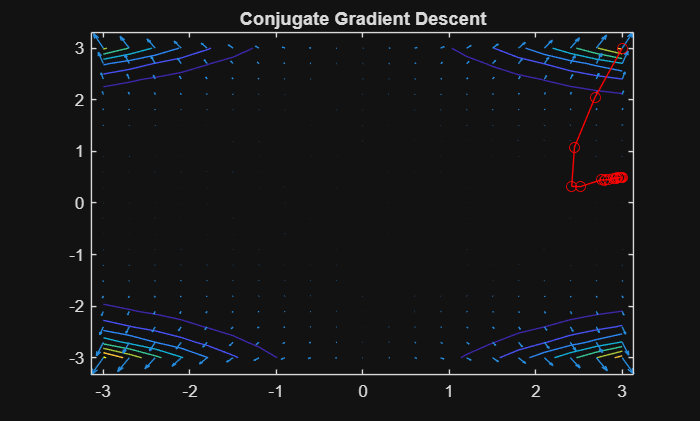

% Task 7
close all
clc

[x,y]=meshgrid(-3:.3:3);
z = (1.5 - x + x.*y).^2 + (2.25 - x + x.*y.^2).^2 + (2.625 - x + x.*y.^3).^2;
figure(1)
hold off
contour(x,y,z)
[dx,dy]=gradient(z,.3,.3);
hold on
quiver(x,y,dx,dy)
title('Conjugate Gradient Descent')

x=[3,3];
xs=x;
itsk=50;

g_prev = gradient1(xs);
s = -g_prev;

for i=1:itsk

    if s*g_prev' >= 0
        s = -g_prev;
    end

    d = s / norm(s);

    step = fminbnd(@(step) ...
        (1.5 - (xs(1)+step*d(1)) + (xs(1)+step*d(1))*(xs(2)+step*d(2)))^2 + ...
        (2.25 - (xs(1)+step*d(1)) + (xs(1)+step*d(1))*(xs(2)+step*d(2))^2)^2 + ...
        (2.625 - (xs(1)+step*d(1)) + (xs(1)+step*d(1))*(xs(2)+step*d(2))^3)^2, ...
        0,1);

    x = xs + step*d;
    plot([xs(1),x(1)],[xs(2),x(2)],'r',[xs(1),x(1)],[xs(2),x(2)],'ro')

    g_new = gradient1(x);
    beta = (g_new*g_new')/(g_prev*g_prev');
    s = -g_new + beta*s;

    xs = x;
    g_prev = g_new;
end

xs

xs =     2.9999    0.4999


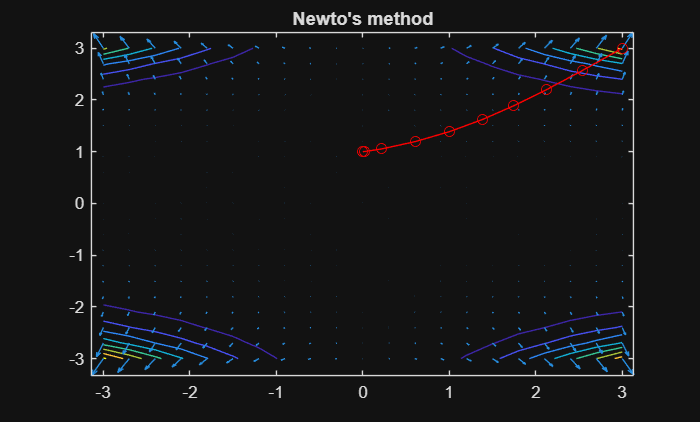

% Task 8
close all
clc

[x,y]=meshgrid(-3:.3:3);
z = (1.5 - x + x.*y).^2 + (2.25 - x + x.*y.^2).^2 + (2.625 - x + x.*y.^3).^2;
figure(1)
hold off
contour(x,y,z)
[dx,dy]=gradient(z,.3,.3);
hold on
quiver(x,y,dx,dy)
title('Newto''s method')

x=[3,3];
xs=x;
itsk=20;

for i=1:itsk

    g = gradient1(xs);
    H = hessian1(xs);

    x = xs - g/H;

    plot([xs(1),x(1)],[xs(2),x(2)],'r',[xs(1),x(1)],[xs(2),x(2)],'ro')

    xs=x;
end

xs

xs =      0     1
